clc;
clear;
urlwrite("https://cecas.clemson.edu/~ahoover/ece854/labs/sin-data.txt","measurement_Q1.txt")

ans = 'C:\Users\shubh\OneDrive - Clemson University\CUICAR\fall_2022\ece8540\assignments\lab4\measurement_Q1.txt'

inp_filename = "measurement_Q1.txt"

inp_filename = "measurement_Q1.txt"

fid = fopen(inp_filename); % open the file
iCtr = 0;
y_q1=[];
true_x_q1=[];
while ~feof(fid) % loop over the following until the end of the file is reached.
  line = fgets(fid); % read in one line
  data1 = strsplit(line);
  true_x_q1(end+1) = str2double(data1(1));
  y_q1(end+1) = str2double(data1(2));
end
  true_x_q1=(true_x_q1)';
  y_q1=(y_q1)';


%assuming a time array corresponding with measurement data with a frequency of 1Hz
time_q1=(1:0.5:length(y_q1)/2);

%assuming a position array corresponding with a predicted state in column 1
%and an updated state in column 2
x_q1=zeros(length(y_q1),2);
x_dot_q1=zeros(length(y_q1),2);
h_q1=zeros(length(y_q1),2);

%assuming initial x and x_dot to be zero and height equal to measurement
x_q1(1,1:end) = 0;
x_dot_q1(1,1:end) = 0;
h_q1(1,1:end) = y_q1(1)*0.9;

%state vector containing both predicted and updated values
X_q1 = [x_q1(1,1:end); x_dot_q1(1,1:end); h_q1(1,1:end)];
X_arr = [];

X_arr{end+1}=X_q1;

% X = [x_q1_pred, x_q1_upd
%     x_dot_pred, x_dot_upd
%     h_pred, h_upd]

%   X = [   x_q1     x_dot_q1(t)   h(t) ]
%   Y = [d(t)


noise_x = 0.03;
noise_y = 0.001;
%for first calculations of f and g, i.e. using the 1 timestamp values to calculate predicted states of timestamp 2

%    x_q1(t+1)          x_dot(t+1)           h(t+1)
f=zeros(length(y_q1),3);
%f(end+1) = [X(1,1) + X(2,1)*T; X(2,1) + noise_x; sind(X(3,1)/10)] %f(0)
%   d(t)
g = zeros(length(y_q1),1); %g(0)
%g = [y_q1(2)]; %g(1)

    "done"



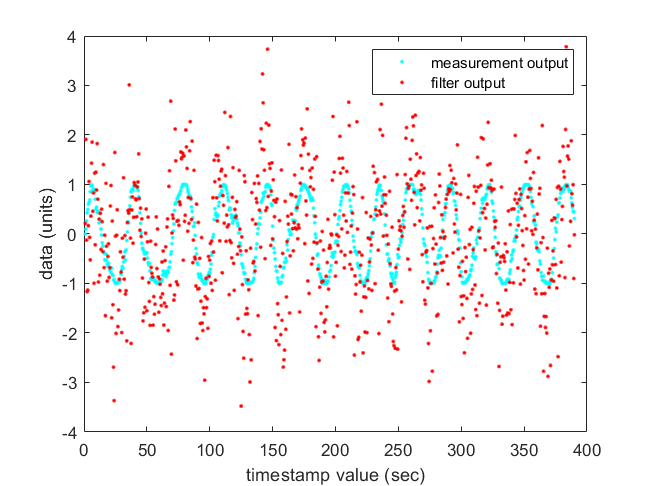

%we know that there's measurement noises and dynamic noises
S_prev_q1 = [1 0 0; 0 1 0; 0 0 1];
S_next_q1 = 0;
df_da = [0 0 0; 0 1 0; 0 0 0];
dg_dx = [0 0 1];
dg_dn = [1];
Q = [0 0 0; 0 noise_x^2 0; 0 0 0];
R = [noise_y^2];

Kalman_filter(X_q1, X_arr, y_q1, true_x_q1, time_q1, S_prev_q1, S_next_q1, R, Q, df_da, dg_dx, dg_dn, noise_x, noise_y, 2);

### Increasing the measurement noise so that the filter relies more on the prediction

    "done"



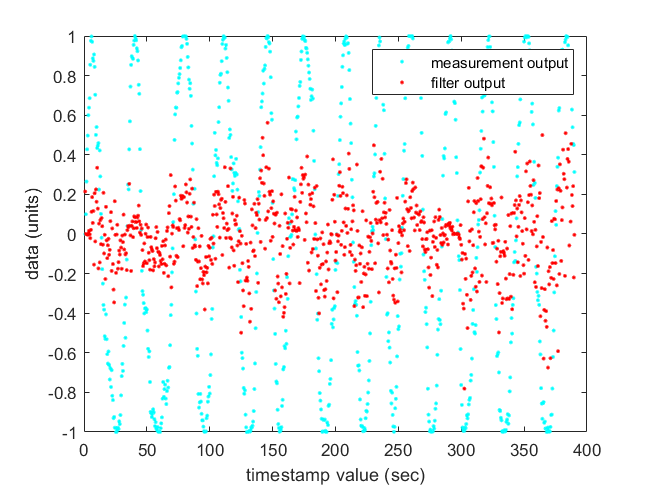


%state vector containing both predicted and updated values
X_q1_2 = [x_q1(1,1:end); x_dot_q1(1,1:end); h_q1(1,1:end)];
X_arr_2 = [];

X_arr_2{end+1}=X_q1_2;


noise_x_2 = 0.1e-1;
noise_y_2 = 10;
S_prev_q1 = [1 0 0; 0 1 0; 0 0 1];
S_next_q1 = 0;
df_da = [0 0 0; 0 1 0; 0 0 0];
dg_dx = [0 0 1];
dg_dn = [1];
Q_2 = [0 0 0; 0 noise_x_2^2 0; 0 0 0];
R_2 = [noise_y_2^2];

Kalman_filter(X_q1_2, X_arr_2, y_q1, true_x_q1, time_q1, S_prev_q1, S_next_q1, R_2, Q_2, df_da, dg_dx, dg_dn, noise_x_2, noise_y_2, 3);

### Increasing the dynamic noise so that the filter relies more on the measurement

    "done"



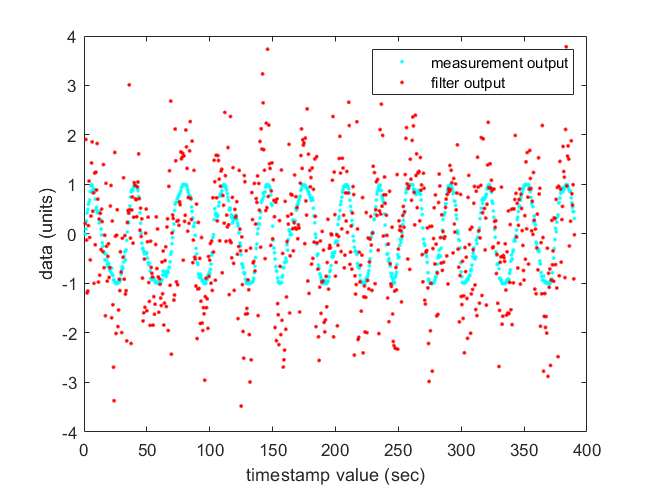


%state vector containing both predicted and updated values
X_q1_3 = [x_q1(1,1:end); x_dot_q1(1,1:end); h_q1(1,1:end)];
X_arr_3 = [];

X_arr_3{end+1}=X_q1_3;


noise_x_3 = 500;
noise_y_3 = 0.0001;
S_prev_q1 = [1 0 0; 0 1 0; 0 0 1];
S_next_q1 = 0;
df_da = [0 0 0; 0 1 0; 0 0 0];
dg_dx = [0 0 1];
dg_dn = [1];
Q_3 = [0 0 0; 0 noise_x_3^2 0; 0 0 0];
R_3 = [noise_y_3^2];

Kalman_filter(X_q1_3, X_arr_3, y_q1, true_x_q1, time_q1, S_prev_q1, S_next_q1, R_3, Q_3, df_da, dg_dx, dg_dn, noise_x_3, noise_y_3, 4);

function Kalman_filter(X_q1, X_arr, y_q1, true_x_q1, time_q1, S_prev_q1, S_next_q1, R, Q, df_da, dg_dx, dg_dn, noise_x, noise_y, fignum)
    
    for i=2:1:length(y_q1)-1
        
        %step 1: Predict next state
        f = [X_q1(1,2) + X_q1(2,2)*(time_q1(i)-time_q1(i-1)); X_q1(2,2) + noise_x; sind(X_q1(3,2)/10)]; %f(1)
        X_q1(1,1)=f(1);
        X_q1(2,1)=f(2);
        X_q1(3,1)=f(3);
        
        %step 2: predict next state covariance
        df_dx = [1 time_q1(i) 0; 0 1 0; ((1/10)*cosd(f(1,1)/10)) 0 0];
        S_next_q1 = df_dx*S_prev_q1*df_dx' + df_da*Q*df_da';
    
        %step 3: obtain measurements (there as input)
        g = f(3);
    
        %step 4: calculate Kalman Gain
        K_q1 = S_next_q1*(dg_dx)'*((dg_dx*S_next_q1*(dg_dx)'+ dg_dn*R*dg_dn')^-1);
    
        %step 5: update state
        X_upd_q1 = f + K_q1*(y_q1(i)-(g));

        %placing predictions in the state variable array
        X_q1(1,2)=X_upd_q1(1);
        X_q1(2,2)=X_upd_q1(2);
        X_q1(3,2)=X_upd_q1(3);
        X_arr{end+1}=X_q1;
    
        %step 6: update state covariance
        S_prev_q1 = [eye(3,3) - K_q1*dg_dx]*S_next_q1;
    end
    display("done");

    X_arr_mat = cell2mat(X_arr);

    figure(fignum)
    plot(time_q1',true_x_q1(1:end-1),'.c')
    ylabel('data (units)');
    xlabel('timestamp value (sec)');
    hold on;
    plot(time_q1',X_arr_mat(3,2:2:end),'.r');
    hold off;
    legend('measurement output','filter output','location','northeast');
end